Reading skeleton file: t2_skeleton.png
Running FindBranchesPores...
3 objects, keeping only the biggest


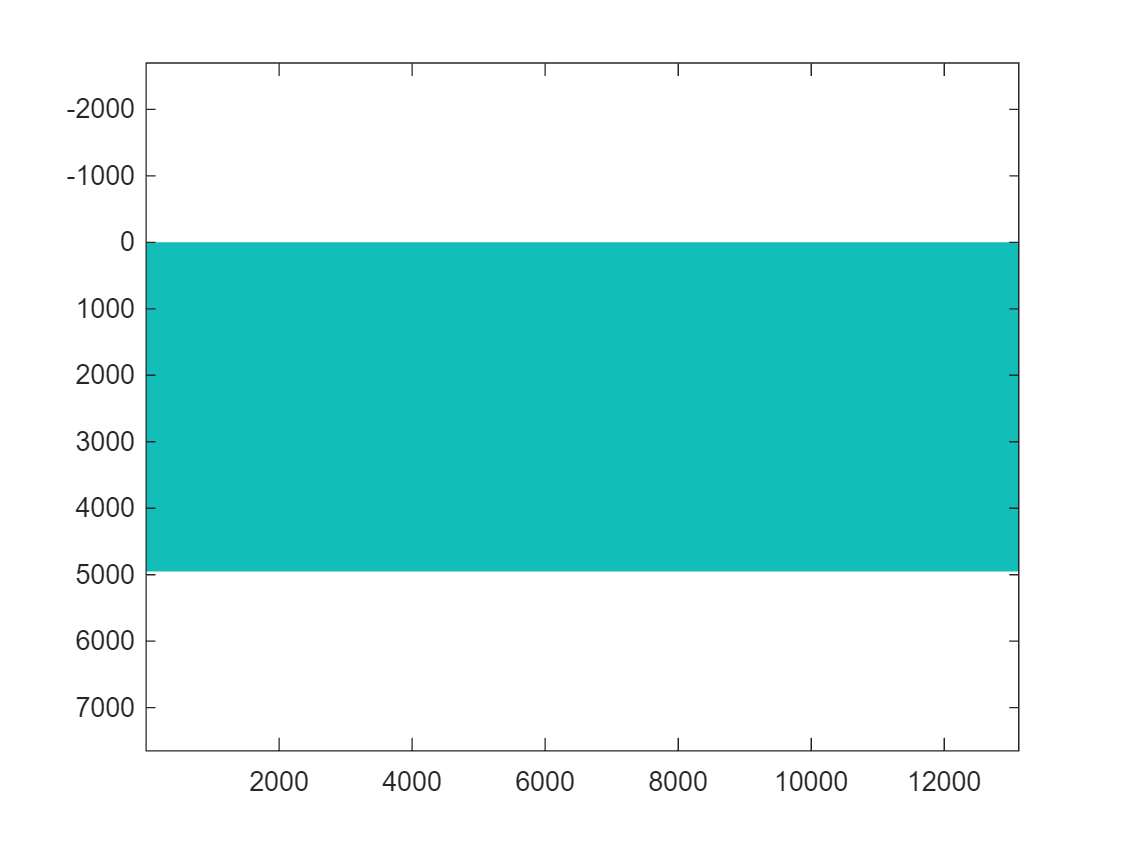

%% =========================================================
%  CLEAN BRANCH TRACKING FROM EXISTING SKELETONS
% ==========================================================

clc; clear; close all;

%% -------------------------
% INPUT FILES
% -------------------------
skelFile1 = "t2_skeleton.png";
skelFile2 = "t3_skeleton.png";

%% -------------------------
% EXTRACTION SETTINGS
% -------------------------
minEdgePix = 4;   % remove tiny edge artifacts after extraction

%% -------------------------
% TRACKING SETTINGS
% -------------------------
scoreP.maxCentroidDist = 250;   % max distance between branch centers (global position gate)
scoreP.maxMidDist      = 250;   % max distance between branch midpoints (shape alignment gate)
scoreP.maxEndDist      = 300;   % max distance between endpoints (topology consistency gate)

scoreP.maxAngleDiff    = 60;    % max allowed orientation difference in degrees (direction similarity)

scoreP.minScore        = 0.5;  % minimum score required to accept a match (confidence threshold)
scoreP.keepTopK        = 5;     % keep only top K candidates per branch (controls splitting vs 1-to-1)

scoreP.ShowProgress    = true;  % display progress during tracking (debugging only)


scoreP.wCentroid = 0.30;  % weight of centroid distance (global position importance)
scoreP.wMid      = 0.30;  % weight of midpoint distance (local shape alignment)
scoreP.wAngle    = 0.15;  % weight of angle similarity (orientation matching)
scoreP.wLength   = 0.15;  % weight of length similarity (size consistency)
scoreP.wEnds     = 0.10;  % weight of endpoint distance (connectivity preservation)
scoreP.wDegree   = 0.00;  % weight of node degree similarity (junction complexity, often noisy)

%% -------------------------
% LOAD + EXTRACT
% -------------------------
[edges1, verts1, branch1, G1, C1, BW1] = skeletonFileToGraph_Direct(skelFile1);

Reading skeleton file: t3_skeleton.png
Running FindBranchesPores...
4 objects, keeping only the biggest


[edges2, verts2, branch2, G2, C2, BW2] = skeletonFileToGraph_Direct(skelFile2);


[edges1, verts1, branch1] = removeShortEdges(edges1, verts1, branch1, minEdgePix);
[edges2, verts2, branch2] = removeShortEdges(edges2, verts2, branch2, minEdgePix);

C1 = buildConnectivity(edges1, size(verts1,1));
C2 = buildConnectivity(edges2, size(verts2,1));
G1 = graph(C1);
G2 = graph(C2);

fprintf('t1: %d edges, %d vertices\n', size(edges1,1), size(verts1,1));

t1: 693 edges, 509 vertices


fprintf('t2: %d edges, %d vertices\n', size(edges2,1), size(verts2,1));

t2: 649 edges, 474 vertices


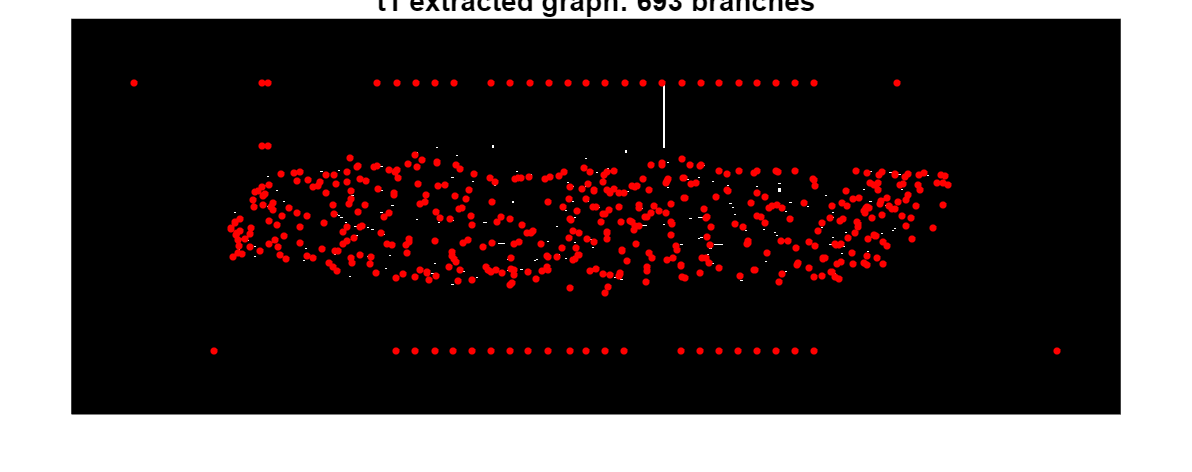


%% -------------------------
% EXTRACTION CHECK
% -------------------------
figure('Name','Extraction Check t1','Color','w');
imshow(BW1); hold on;
plot(verts1(:,2), verts1(:,1), 'r.', 'MarkerSize', 8);
title(sprintf('t1 extracted graph: %d branches', numel(branch1)));

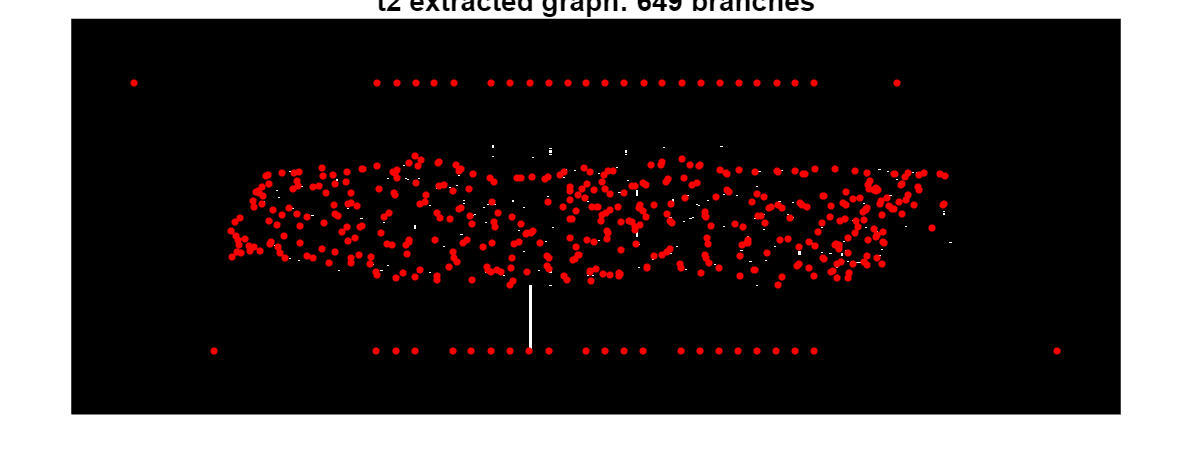


figure('Name','Extraction Check t2','Color','w');
imshow(BW2); hold on;
plot(verts2(:,2), verts2(:,1), 'r.', 'MarkerSize', 8);
title(sprintf('t2 extracted graph: %d branches', numel(branch2)));


%% -------------------------
% TRACKING
% -------------------------
track2 = trackBranchesByScoringMultiMatch(verts1, edges1, branch1, ...
                                          verts2, edges2, branch2, ...
                                          scoreP);

Scoring-based multi-match tracking...
  processed 50 / 693 branches in t1
  processed 100 / 693 branches in t1
  processed 150 / 693 branches in t1
  processed 200 / 693 branches in t1
  processed 250 / 693 branches in t1
  processed 300 / 693 branches in t1
  processed 350 / 693 branches in t1
  processed 400 / 693 branches in t1
  processed 450 / 693 branches in t1
  processed 500 / 693 branches in t1
  processed 550 / 693 branches in t1
  processed 600 / 693 branches in t1
  processed 650 / 693 branches in t1

===== SCORING TRACK SUMMARY =====
t1 branches with >=1 candidate: 670 / 693 (96.7%)
t2 branches with parent:        632 / 649 (97.4%)
1-to-1 branches: 169
split-like branches: 501
vanished branches t1: 23
new branches t2: 17



=== Diagnostic for branch 10 ===
Best centroid distance: 36.35
Best midpoint distance: 38.02
Best endpoint distance: 46.37
Best angle difference: 0.11
Max score: 0.736
Matches above threshold: 3


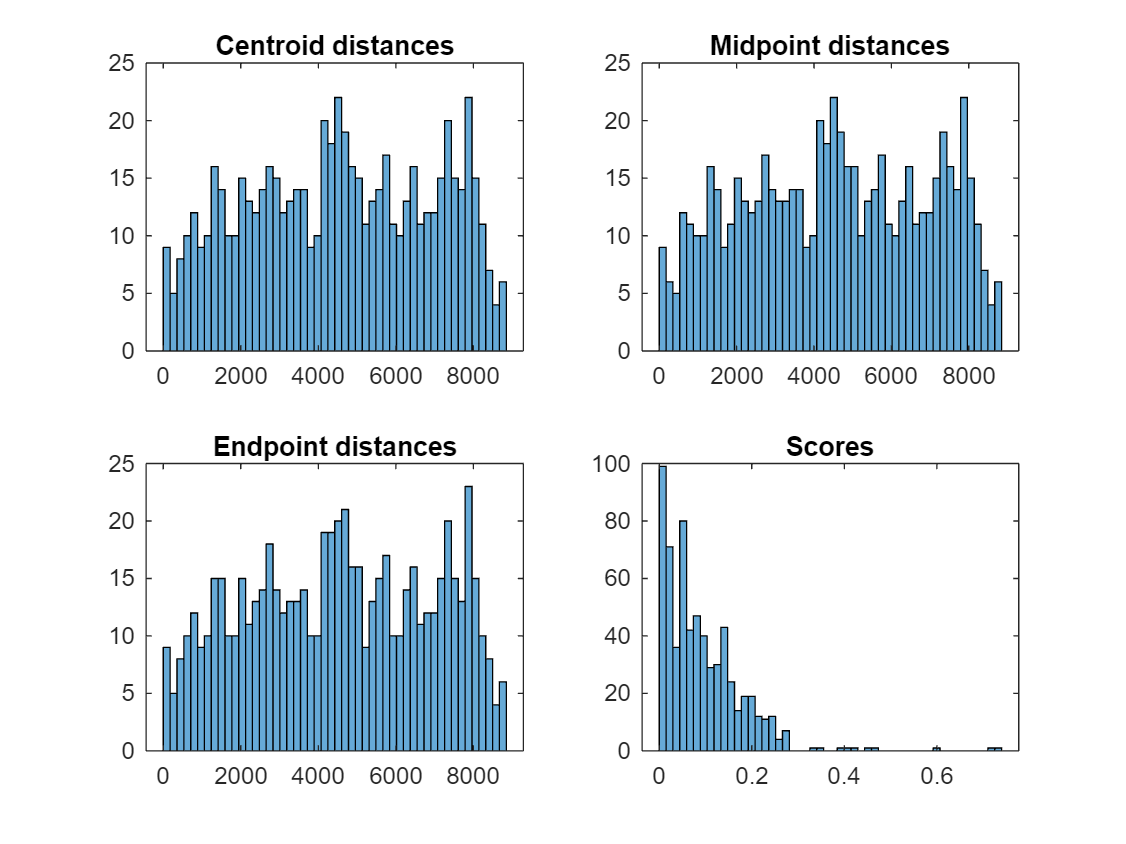


%% -------------------------
% EXTRA DIAGNOSTIC FOR ONE BRANCH
% -------------------------
exampleBranch = 10;
if exampleBranch >= 1 && exampleBranch <= numel(branch1)
    runScoreDiagnostic(exampleBranch, branch1, edges1, verts1, ...
                       branch2, edges2, verts2, scoreP);
end


Starting visualizations...


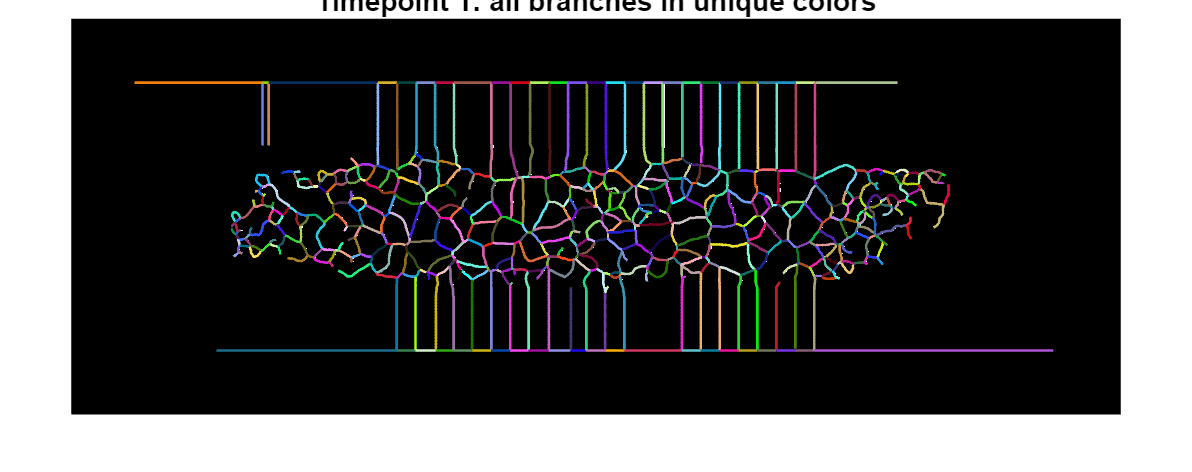

Figure 1 done.


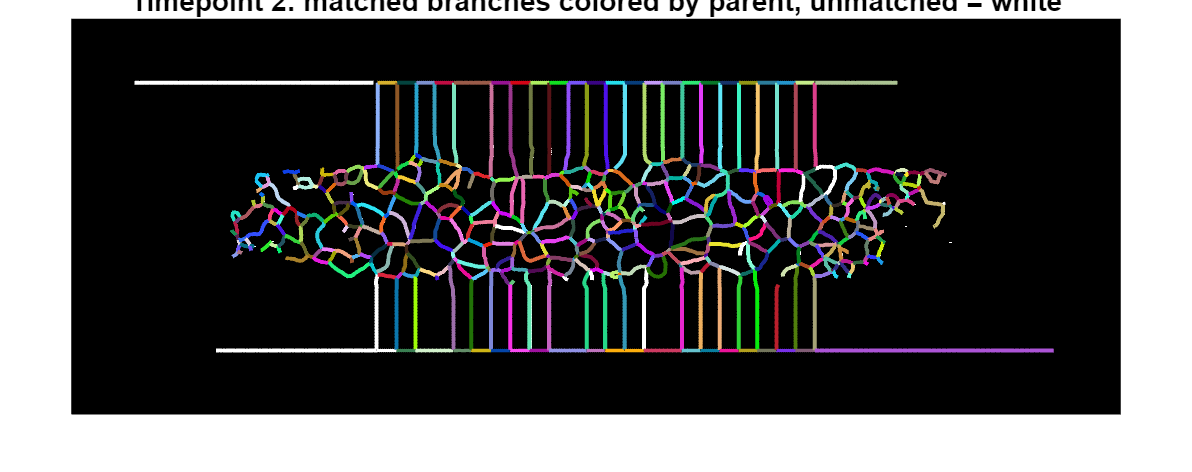

Figure 2 done.


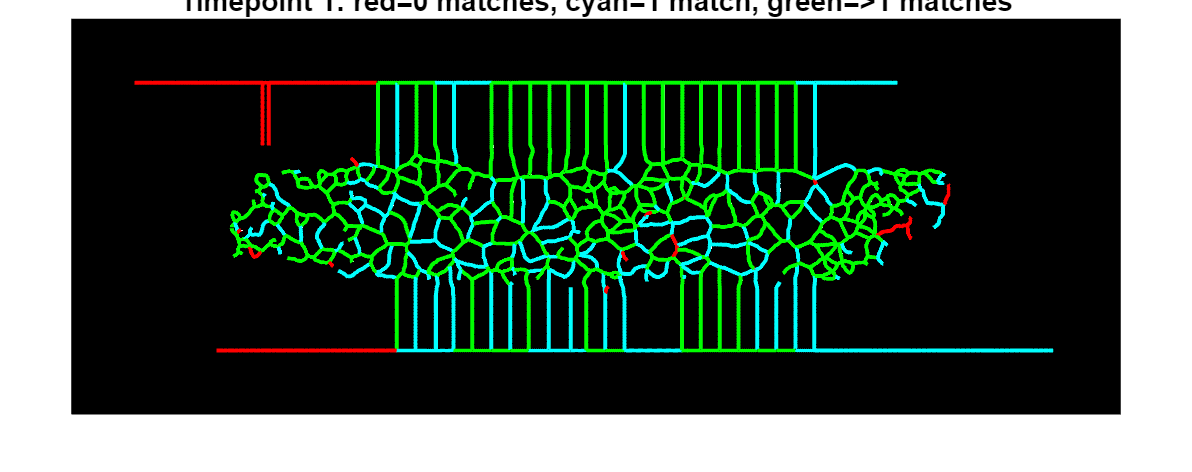

Figure 3 done.


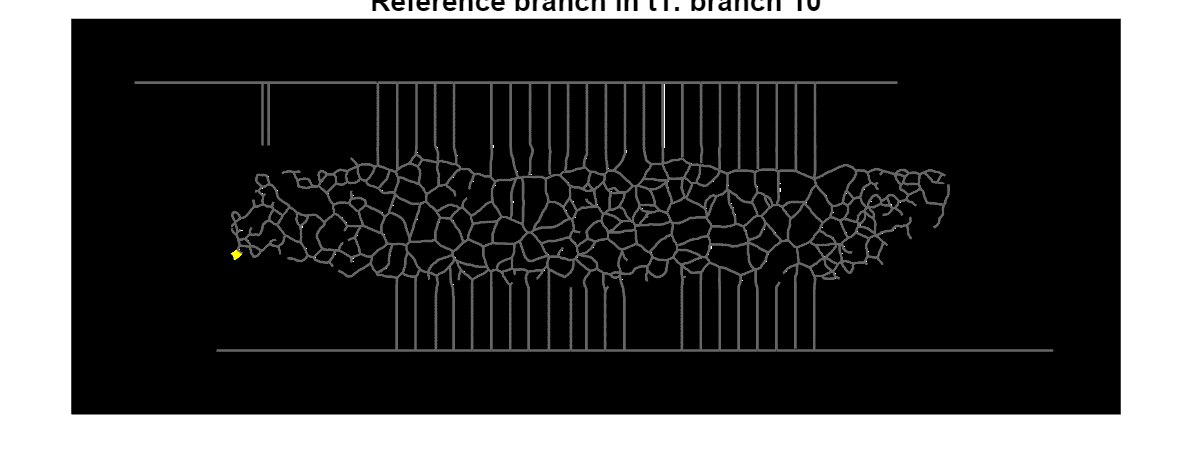

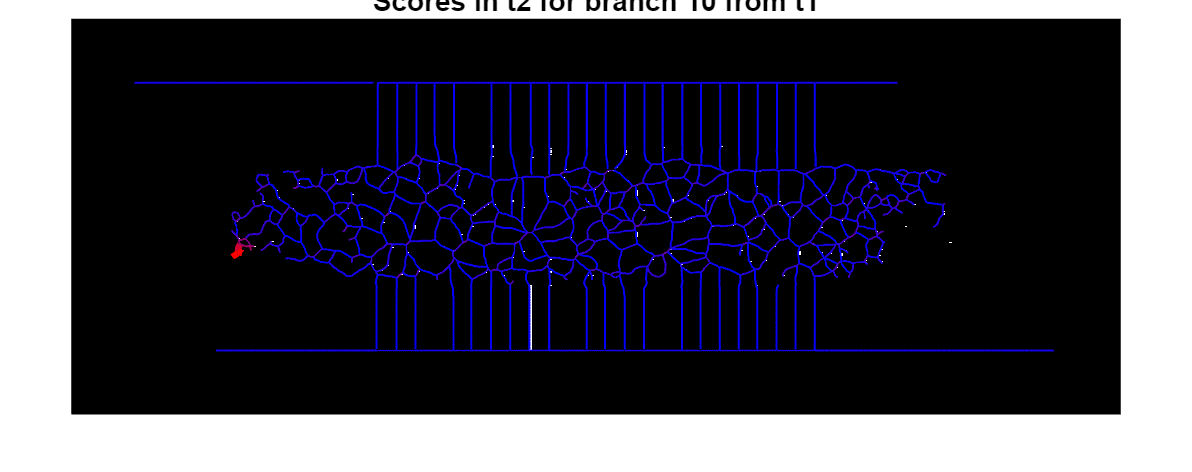

Figure 4 done.



%% -------------------------
% VISUALIZATIONS
% -------------------------
plotTrackingVisualizations(BW1, BW2, branch1, branch2, edges1, edges2, verts1, verts2, track2, scoreP, exampleBranch);


%% =========================================================
% FUNCTIONS
% ==========================================================

function [edges, vertices, branch, G, C, BW_skeleton] = skeletonFileToGraph_Direct(skelFile)
% Load a precomputed skeleton image and extract branches using FindBranchesPores.
% Requires FindBranchesPores on the MATLAB path.

    fprintf('Reading skeleton file: %s\n', skelFile);
    bw = imread(skelFile);

    if ndims(bw) == 3
        bw = rgb2gray(bw);
    end

    if islogical(bw)
        BW_skeleton = bw;
    else
        BW_skeleton = bw > 0;
    end

    BW_skeleton = logical(BW_skeleton);
    BW_skeleton = bwmorph(BW_skeleton, 'skel', inf);

    % For this direct workflow, use the skeleton itself as mask placeholder
    pores = double(BW_skeleton);

    fprintf('Running FindBranchesPores...\n');
    [edges, vertices, branch, ~] = FindBranchesPores('./', BW_skeleton, pores);

    assert(size(edges,1) == numel(branch), 'Mismatch: number of edges != number of branches');

    % Reorient edges downward in y for consistency
    for i = 1:size(edges,1)
        inorg = edges(i,1);
        indest = edges(i,2);

        org  = vertices(inorg,:);
        dest = vertices(indest,:);

        if dest(1) < org(1)
            edges(i,1) = indest;
            edges(i,2) = inorg;
            branch{i} = flipud(branch{i});
        end
    end

    C = buildConnectivity(edges, size(vertices,1));
    G = graph(C);
end

function track = trackBranchesByScoringMultiMatch(verts1, edges1, branch1, ...
                                                  verts2, edges2, branch2, p)

    if nargin < 7, p = struct; end

    p = setScDefault(p,'maxCentroidDist',800);
    p = setScDefault(p,'maxMidDist',800);
    p = setScDefault(p,'maxEndDist',1000);
    p = setScDefault(p,'maxAngleDiff',180);
    p = setScDefault(p,'minScore',0.15);
    p = setScDefault(p,'keepTopK',10);
    p = setScDefault(p,'ShowProgress',true);

    p = setScDefault(p,'wCentroid',0.45);
    p = setScDefault(p,'wMid',0.45);
    p = setScDefault(p,'wAngle',0.00);
    p = setScDefault(p,'wLength',0.10);
    p = setScDefault(p,'wEnds',0.00);
    p = setScDefault(p,'wDegree',0.00);

    nE1 = size(edges1,1);
    nE2 = size(edges2,1);

    deg1 = nodeDegrees(edges1, size(verts1,1));
    deg2 = nodeDegrees(edges2, size(verts2,1));

    F1 = branchFeatureTable(branch1, edges1, verts1, deg1);
    F2 = branchFeatureTable(branch2, edges2, verts2, deg2);

    % ===== REMOVE GLOBAL COORDINATE OFFSET =====
    allC1 = nan(numel(F1), 2);
    for i = 1:numel(F1)
        c = F1(i).centroid;
        if numel(c) == 2
            allC1(i,:) = c(:).';
        end
    end

    allC2 = nan(numel(F2), 2);
    for i = 1:numel(F2)
        c = F2(i).centroid;
        if numel(c) == 2
            allC2(i,:) = c(:).';
        end
    end

    ref1 = mean(allC1, 1, 'omitnan');
    ref2 = mean(allC2, 1, 'omitnan');

    for i = 1:numel(F1)
        if numel(F1(i).centroid) == 2, F1(i).centroid = F1(i).centroid - ref1; end
        if numel(F1(i).midpoint) == 2, F1(i).midpoint = F1(i).midpoint - ref1; end
        if numel(F1(i).end1) == 2,     F1(i).end1     = F1(i).end1     - ref1; end
        if numel(F1(i).end2) == 2,     F1(i).end2     = F1(i).end2     - ref1; end
    end

    for i = 1:numel(F2)
        if numel(F2(i).centroid) == 2, F2(i).centroid = F2(i).centroid - ref2; end
        if numel(F2(i).midpoint) == 2, F2(i).midpoint = F2(i).midpoint - ref2; end
        if numel(F2(i).end1) == 2,     F2(i).end1     = F2(i).end1     - ref2; end
        if numel(F2(i).end2) == 2,     F2(i).end2     = F2(i).end2     - ref2; end
    end

    candidateMap12 = cell(nE1,1);
    scoreMap12     = cell(nE1,1);

    bestParent2 = zeros(nE2,1,'int32');
    bestScore2  = zeros(nE2,1);

    if p.ShowProgress
        fprintf('Scoring-based multi-match tracking...\n');
    end

    for e1 = 1:nE1
        scores = zeros(nE2,1);

        for e2 = 1:nE2
            scores(e2) = branchPairScore(F1(e1), F2(e2), p);
        end

        idx = find(scores >= p.minScore);

        if ~isempty(idx)
            [srt, ord] = sort(scores(idx), 'descend');
            idx = idx(ord);

            if numel(idx) > p.keepTopK
                idx = idx(1:p.keepTopK);
                srt = srt(1:p.keepTopK);
            end

            candidateMap12{e1} = idx(:)';
            scoreMap12{e1}     = srt(:)';

            for k = 1:numel(idx)
                e2 = idx(k);
                if scores(e2) > bestScore2(e2)
                    bestScore2(e2) = scores(e2);
                    bestParent2(e2) = e1;
                end
            end
        else
            candidateMap12{e1} = [];
            scoreMap12{e1} = [];
        end

        if p.ShowProgress && mod(e1,50)==0
            fprintf('  processed %d / %d branches in t1\n', e1, nE1);
        end
    end

    oneToOne = [];
    splitLike = [];
    vanished = [];

    for e1 = 1:nE1
        nc = numel(candidateMap12{e1});
        if nc == 0
            vanished(end+1,1) = e1; %#ok<AGROW>
        elseif nc == 1
            oneToOne(end+1,1) = e1; %#ok<AGROW>
        else
            splitLike(end+1,1) = e1; %#ok<AGROW>
        end
    end

    newEdges2 = find(bestParent2 == 0);

    track.candidateMap12 = candidateMap12;
    track.scoreMap12     = scoreMap12;
    track.bestParent2    = bestParent2;
    track.bestScore2     = bestScore2;
    track.oneToOne       = oneToOne;
    track.splitLike      = splitLike;
    track.vanished1      = vanished;
    track.newEdges2      = newEdges2;
    track.covered2       = find(bestParent2 > 0);
    track.coverageT2     = 100 * nnz(bestParent2 > 0) / nE2;
    track.coverageT1     = 100 * nnz(cellfun(@(x) ~isempty(x), candidateMap12)) / nE1;

    fprintf('\n===== SCORING TRACK SUMMARY =====\n');
    fprintf('t1 branches with >=1 candidate: %d / %d (%.1f%%)\n', ...
        nnz(cellfun(@(x) ~isempty(x), candidateMap12)), nE1, track.coverageT1);
    fprintf('t2 branches with parent:        %d / %d (%.1f%%)\n', ...
        nnz(bestParent2 > 0), nE2, track.coverageT2);
    fprintf('1-to-1 branches: %d\n', numel(oneToOne));
    fprintf('split-like branches: %d\n', numel(splitLike));
    fprintf('vanished branches t1: %d\n', numel(vanished));
    fprintf('new branches t2: %d\n', numel(newEdges2));
end

function plotTrackingVisualizations(BW1, BW2, branch1, branch2, edges1, edges2, verts1, verts2, track2, scoreP, exampleBranch)

    assert(numel(branch1) == size(edges1,1), 'branch1 and edges1 size mismatch');
    assert(numel(branch2) == size(edges2,1), 'branch2 and edges2 size mismatch');
    assert(numel(track2.candidateMap12) == numel(branch1), 'track2.candidateMap12 size mismatch');
    assert(numel(track2.bestParent2) == numel(branch2), 'track2.bestParent2 size mismatch');

    nE1 = numel(branch1);
    nE2 = numel(branch2);

    rng(1);
    cols1 = rand(nE1,3);

    fprintf('\nStarting visualizations...\n');

    % Figure 1
    figure('Name','Figure 1 - t1 all branches','Color','w');
    imshow(BW1); hold on;
    title('Timepoint 1: all branches in unique colors');
    for e1 = 1:nE1
        p = branch1{e1};
        if isempty(p), continue; end
        step = max(1, round(size(p,1)/50));
        plot(p(1:step:end,2), p(1:step:end,1), '-', 'Color', cols1(e1,:), 'LineWidth', 1);
    end
    drawnow;
    fprintf('Figure 1 done.\n');

    % Figure 2
    figure('Name','Figure 2 - t2 matched by parent color','Color','w');
    imshow(BW2); hold on;
    title('Timepoint 2: matched branches colored by parent, unmatched = white');
    for e2 = 1:nE2
        p = branch2{e2};
        if isempty(p), continue; end
        step = max(1, round(size(p,1)/50));
        parent = track2.bestParent2(e2);
        if parent > 0
            c = cols1(parent,:);
        else
            c = [1 1 1];
        end
        plot(p(1:step:end,2), p(1:step:end,1), '-', 'Color', c, 'LineWidth', 1.5);
    end
    drawnow;
    fprintf('Figure 2 done.\n');

    % Figure 3
    figure('Name','Figure 3 - t1 classification','Color','w');
    imshow(BW1); hold on;
    title('Timepoint 1: red=0 matches, cyan=1 match, green=>1 matches');
    for e1 = 1:nE1
        p = branch1{e1};
        if isempty(p), continue; end
        step = max(1, round(size(p,1)/50));

        nMatch = numel(track2.candidateMap12{e1});
        if nMatch == 0
            c = [1 0 0];
        elseif nMatch == 1
            c = [0 1 1];
        else
            c = [0 1 0];
        end

        plot(p(1:step:end,2), p(1:step:end,1), '-', 'Color', c, 'LineWidth', 1.5);
    end
    drawnow;
    fprintf('Figure 3 done.\n');

    % Figure 4a
    if exampleBranch >= 1 && exampleBranch <= nE1
        figure('Name','Figure 4a - reference branch in t1','Color','w');
        imshow(BW1); hold on;
        title(sprintf('Reference branch in t1: branch %d', exampleBranch));
        for e1 = 1:nE1
            p = branch1{e1};
            if isempty(p), continue; end
            step = max(1, round(size(p,1)/50));
            plot(p(1:step:end,2), p(1:step:end,1), '-', 'Color', [0.4 0.4 0.4], 'LineWidth', 1);
        end
        pRef = branch1{exampleBranch};
        step = max(1, round(size(pRef,1)/50));
        plot(pRef(1:step:end,2), pRef(1:step:end,1), 'y-', 'LineWidth', 3);

        % Figure 4b
        deg1 = nodeDegrees(edges1, size(verts1,1));
        deg2 = nodeDegrees(edges2, size(verts2,1));
        F1 = branchFeatureTable(branch1, edges1, verts1, deg1);
        F2 = branchFeatureTable(branch2, edges2, verts2, deg2);

        % same centering as tracker
        allC1 = nan(numel(F1), 2);
        for i = 1:numel(F1)
            c = F1(i).centroid;
            if numel(c) == 2, allC1(i,:) = c(:).'; end
        end
        allC2 = nan(numel(F2), 2);
        for i = 1:numel(F2)
            c = F2(i).centroid;
            if numel(c) == 2, allC2(i,:) = c(:).'; end
        end
        ref1 = mean(allC1, 1, 'omitnan');
        ref2 = mean(allC2, 1, 'omitnan');

        for i = 1:numel(F1)
            if numel(F1(i).centroid) == 2, F1(i).centroid = F1(i).centroid - ref1; end
            if numel(F1(i).midpoint) == 2, F1(i).midpoint = F1(i).midpoint - ref1; end
            if numel(F1(i).end1) == 2, F1(i).end1 = F1(i).end1 - ref1; end
            if numel(F1(i).end2) == 2, F1(i).end2 = F1(i).end2 - ref1; end
        end
        for i = 1:numel(F2)
            if numel(F2(i).centroid) == 2, F2(i).centroid = F2(i).centroid - ref2; end
            if numel(F2(i).midpoint) == 2, F2(i).midpoint = F2(i).midpoint - ref2; end
            if numel(F2(i).end1) == 2, F2(i).end1 = F2(i).end1 - ref2; end
            if numel(F2(i).end2) == 2, F2(i).end2 = F2(i).end2 - ref2; end
        end

        scores = zeros(nE2,1);
        for e2 = 1:nE2
            scores(e2) = branchPairScore(F1(exampleBranch), F2(e2), scoreP);
        end

        if max(scores) > 0
            scoresNorm = scores / max(scores);
        else
            scoresNorm = scores;
        end

        figure('Name','Figure 4b - score map in t2','Color','w');
        imshow(BW2); hold on;
        title(sprintf('Scores in t2 for branch %d from t1', exampleBranch));

        for e2 = 1:nE2
            p = branch2{e2};
            if isempty(p), continue; end
            step = max(1, round(size(p,1)/50));
            c = [scoresNorm(e2), 0, 1 - scoresNorm(e2)];
            if scores(e2) >= scoreP.minScore
                lw = 2.5;
            else
                lw = 0.75;
            end
            plot(p(1:step:end,2), p(1:step:end,1), '-', 'Color', c, 'LineWidth', lw);
        end
        drawnow;
        fprintf('Figure 4 done.\n');
    end
end

function runScoreDiagnostic(exampleBranch, branch1, edges1, verts1, branch2, edges2, verts2, scoreP)

    deg1 = nodeDegrees(edges1, size(verts1,1));
    deg2 = nodeDegrees(edges2, size(verts2,1));

    F1 = branchFeatureTable(branch1, edges1, verts1, deg1);
    F2 = branchFeatureTable(branch2, edges2, verts2, deg2);

    % same centering as tracker
    allC1 = nan(numel(F1), 2);
    for i = 1:numel(F1)
        c = F1(i).centroid;
        if numel(c) == 2, allC1(i,:) = c(:).'; end
    end
    allC2 = nan(numel(F2), 2);
    for i = 1:numel(F2)
        c = F2(i).centroid;
        if numel(c) == 2, allC2(i,:) = c(:).'; end
    end
    ref1 = mean(allC1, 1, 'omitnan');
    ref2 = mean(allC2, 1, 'omitnan');

    for i = 1:numel(F1)
        if numel(F1(i).centroid) == 2, F1(i).centroid = F1(i).centroid - ref1; end
        if numel(F1(i).midpoint) == 2, F1(i).midpoint = F1(i).midpoint - ref1; end
        if numel(F1(i).end1) == 2, F1(i).end1 = F1(i).end1 - ref1; end
        if numel(F1(i).end2) == 2, F1(i).end2 = F1(i).end2 - ref1; end
    end
    for i = 1:numel(F2)
        if numel(F2(i).centroid) == 2, F2(i).centroid = F2(i).centroid - ref2; end
        if numel(F2(i).midpoint) == 2, F2(i).midpoint = F2(i).midpoint - ref2; end
        if numel(F2(i).end1) == 2, F2(i).end1 = F2(i).end1 - ref2; end
        if numel(F2(i).end2) == 2, F2(i).end2 = F2(i).end2 - ref2; end
    end

    A = F1(exampleBranch);

    dCent_all = zeros(numel(branch2),1);
    dMid_all  = zeros(numel(branch2),1);
    dEnds_all = zeros(numel(branch2),1);
    dAng_all  = zeros(numel(branch2),1);
    scores_all = zeros(numel(branch2),1);

    for e2 = 1:numel(branch2)
        B = F2(e2);

        if any(isnan(A.centroid)) || any(isnan(B.centroid))
            dCent_all(e2) = NaN;
            dMid_all(e2)  = NaN;
            dEnds_all(e2) = NaN;
            dAng_all(e2)  = NaN;
            scores_all(e2) = 0;
            continue;
        end

        dCent_all(e2) = norm(A.centroid - B.centroid);
        dMid_all(e2)  = norm(A.midpoint - B.midpoint);

        dEnds1 = norm(A.end1 - B.end1) + norm(A.end2 - B.end2);
        dEnds2 = norm(A.end1 - B.end2) + norm(A.end2 - B.end1);
        dEnds_all(e2) = min(dEnds1, dEnds2) / 2;

        dAng = abs(A.angle - B.angle);
        dAng = min(dAng, 180 - dAng);
        dAng = min(dAng, 90);
        dAng_all(e2) = dAng;

        scores_all(e2) = branchPairScore(A, B, scoreP);
    end

    fprintf('\n=== Diagnostic for branch %d ===\n', exampleBranch);
    fprintf('Best centroid distance: %.2f\n', min(dCent_all, [], 'omitnan'));
    fprintf('Best midpoint distance: %.2f\n', min(dMid_all, [], 'omitnan'));
    fprintf('Best endpoint distance: %.2f\n', min(dEnds_all, [], 'omitnan'));
    fprintf('Best angle difference: %.2f\n', min(dAng_all, [], 'omitnan'));
    fprintf('Max score: %.3f\n', max(scores_all));
    fprintf('Matches above threshold: %d\n', nnz(scores_all >= scoreP.minScore));

    figure('Name','Diagnostic distances','Color','w');
    subplot(2,2,1); histogram(dCent_all,50); title('Centroid distances');
    subplot(2,2,2); histogram(dMid_all,50); title('Midpoint distances');
    subplot(2,2,3); histogram(dEnds_all,50); title('Endpoint distances');
    subplot(2,2,4); histogram(scores_all,50); title('Scores');
end

function F = branchFeatureTable(branch, edges, verts, deg)
    nE = size(edges,1);

    F = repmat(struct( ...
        'centroid', [NaN NaN], ...
        'midpoint', [NaN NaN], ...
        'angle', NaN, ...
        'length', 0, ...
        'end1', [NaN NaN], ...
        'end2', [NaN NaN], ...
        'deg1', NaN, ...
        'deg2', NaN), nE, 1);

    for e = 1:nE
        pix = branch{e};

        if isempty(pix) || size(pix,2) < 2
            continue;
        end

        F(e).centroid = mean(pix(:,1:2),1);
        F(e).midpoint = pix(round(end/2),1:2);
        F(e).length   = size(pix,1);

        p1 = pix(1,1:2);
        p2 = pix(end,1:2);
        F(e).end1 = p1;
        F(e).end2 = p2;

        dy = p2(1) - p1(1);
        dx = p2(2) - p1(2);
        ang = atan2d(dy, dx);
        ang = mod(ang,180);
        F(e).angle = ang;

        v1 = edges(e,1);
        v2 = edges(e,2);
        F(e).deg1 = deg(v1);
        F(e).deg2 = deg(v2);
    end
end

function s = branchPairScore(A, B, p)

    if any(isnan(A.centroid)) || any(isnan(B.centroid)) || ...
       any(isnan(A.midpoint)) || any(isnan(B.midpoint)) || ...
       any(isnan(A.end1)) || any(isnan(B.end1)) || ...
       any(isnan(A.end2)) || any(isnan(B.end2)) || ...
       isnan(A.angle) || isnan(B.angle)
        s = 0;
        return;
    end

    dCent = norm(A.centroid - B.centroid);
    dMid  = norm(A.midpoint - B.midpoint);

    dEnds1 = norm(A.end1 - B.end1) + norm(A.end2 - B.end2);
    dEnds2 = norm(A.end1 - B.end2) + norm(A.end2 - B.end1);
    dEnds = min(dEnds1, dEnds2) / 2;

    dAng = abs(A.angle - B.angle);
    dAng = min(dAng, 180 - dAng);
    dAng = min(dAng, 90);

    degDiff1 = abs(A.deg1 - B.deg1) + abs(A.deg2 - B.deg2);
    degDiff2 = abs(A.deg1 - B.deg2) + abs(A.deg2 - B.deg1);
    degDiff = min(degDiff1, degDiff2) / 2;

    lenRel = abs(A.length - B.length) / max(A.length,1);

    scCent = max(0, 1 - dCent / p.maxCentroidDist);
    scMid  = max(0, 1 - dMid  / p.maxMidDist);
    scAng  = max(0, 1 - dAng  / p.maxAngleDiff);
    scLen  = max(0, 1 - min(lenRel,1));
    scEnds = max(0, 1 - dEnds / p.maxEndDist);
    scDeg  = max(0, 1 - min(degDiff / 3, 1));

    s = p.wCentroid * scCent + ...
        p.wMid      * scMid  + ...
        p.wAngle    * scAng  + ...
        p.wLength   * scLen  + ...
        p.wEnds     * scEnds + ...
        p.wDegree   * scDeg;
end

function deg = nodeDegrees(edges, nV)
    deg = zeros(nV,1);
    for i = 1:size(edges,1)
        deg(edges(i,1)) = deg(edges(i,1)) + 1;
        deg(edges(i,2)) = deg(edges(i,2)) + 1;
    end
end

function p = setScDefault(p, name, val)
    if ~isfield(p,name) || isempty(p.(name))
        p.(name) = val;
    end
end

function [edges2, verts2, branch2] = removeShortEdges(edges, verts, branch, minEdgePix)
    if isempty(edges)
        edges2 = edges; verts2 = verts; branch2 = branch; return;
    end

    L = cellfun(@(p) size(p,1), branch);
    keepE = (L > minEdgePix);

    edges2 = edges(keepE,:);
    branch2 = branch(keepE);

    if isempty(edges2)
        verts2 = zeros(0,2);
        edges2 = zeros(0,2);
        branch2 = {};
        return;
    end

    usedV = unique(edges2(:));
    map = zeros(size(verts,1),1,'int32');
    map(usedV) = int32(1:numel(usedV));

    edges2 = [map(edges2(:,1)) map(edges2(:,2))];
    verts2 = verts(usedV,:);
end

function C = buildConnectivity(edges, nV)
    C = zeros(nV);
    for i = 1:size(edges,1)
        a = edges(i,1);
        b = edges(i,2);
        C(a,b) = C(a,b) + 1;
        C(b,a) = C(b,a) + 1;
    end
end

